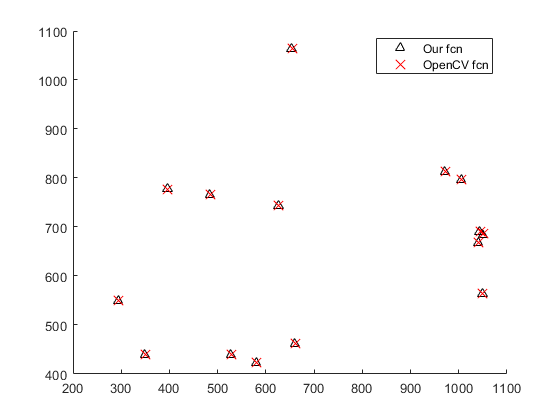

original = imread('stavebnica.jpg');
if size(original,3)>1
   original = rgb2gray(original); 
end
corners = getBestFeatures(original, 100, 5);
% imshow(original);
figure
sc = corners.selectStrongest(15);
hold on
plot(sc.Location(:,1),sc.Location(:,2),'k','Marker','^','LineStyle','none');
hold off

corners = detectMinEigenFeatures(original);
sc = corners.selectStrongest(15);
hold on
% plot(corners.selectStrongest(10));
plot(sc.Location(:,1),sc.Location(:,2),'r','Marker','x','LineStyle','none', 'MarkerSize',10);
hold off
legend("Our fcn", "OpenCV fcn", "Location","best")